clc
close all
clear all
cd('C:\Users\fi95063\Desktop')

data = readtable('stock_price.xls');

data(1:10,:)

ans = 10×4 table
    year    month    day       sp   
    ____    _____    ___    ________

    1957      1       1     0.037439
    1957      2       1     0.035951
    1957      3       1     0.036364
    1957      4       1     0.037356
    1957      5       1     0.038596
    1957      6       1     0.038926
    1957      7       1     0.039587
    1957      8       1     0.037604
    1957      9       1     0.036282
    1957     10       1     0.034133


t = datetime(data.year,data.month,data.day);
sp = data.sp;
T = length(t);

table(t(1:10),data.sp(1:10))

ans = 10×2 table
       Var1          Var2  
    ___________    ________

    01-Jan-1957    0.037439
    01-Feb-1957    0.035951
    01-Mar-1957    0.036364
    01-Apr-1957    0.037356
    01-May-1957    0.038596
    01-Jun-1957    0.038926
    01-Jul-1957    0.039587
    01-Aug-1957    0.037604
    01-Sep-1957    0.036282
    01-Oct-1957    0.034133


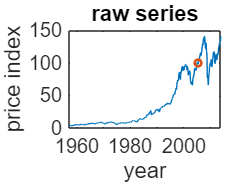

figure(1)
plot(t,sp*100)
hold on
plot(t(582),sp(582)*100,'o','MarkerSize',5,'LineWidth',2)
hold off
title('raw series')
xlabel('year')
ylabel('price index')
set(gca,'FontSize',15)

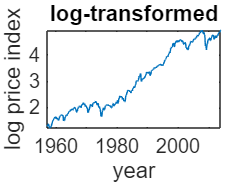

%% DATA TRANSFORMATIONS

l_sp = log(sp*100); %sp*100 is the price index

plot(t,l_sp)
title('log-transformed')
xlabel('year')
ylabel('log price index')
set(gca,'FontSize',15)

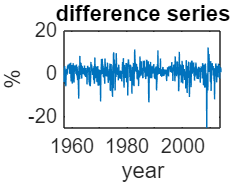

d_sp = diff(l_sp)*100; %diff gives first-difference, hence growth rate, x100 gives percentages.

figure(1)
plot(t(2:end),d_sp)
title('difference series')
xlabel('year')
ylabel('%')
set(gca,'FontSize',15)

%% LINEAR REGRESSION 

trend = 1 : T; %generate a linear time trend
X = [ones([length(l_sp),1]),trend(:)]; %covariates
Y = l_sp; %dependent var
B = X\Y; %MATLAB shortcut to solve A*X = B: the same as OLS solution (X'X)^-1 X'Y

B

B =     1.0694
    0.0057


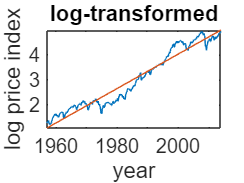

%look at trend
plot(t,l_sp)
title('log-transformed')
xlabel('year')
ylabel('log price index')
set(gca,'FontSize',15)
hold on
plot(t,B(1) + B(2)*trend)
hold off

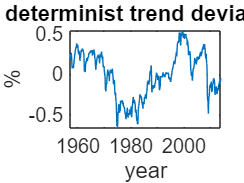


%detrend series
c_sp = Y - X*B; 

plot(t,c_sp)
title('determinist trend deviation')
xlabel('year')
ylabel('%')
set(gca,'FontSize',15)


plot(t(2:end),d_sp)
title('difference series')
xlabel('year')
ylabel('%')
set(gca,'FontSize',15)


% Notes: 1) d_sp corresponds to the growth rate of the stock price index, or stock return

%        2) c_sp is the percentage deviation of the stock price index relative to the linear deterministic trend

%        3) X\Y computes the OLS: hat beta = (X'X)^{-1} (X'Y)

%% AUTOCORRELATIONS

acf1 = autocorr(d_sp, 'NumLags', 18);
acf2 = autocorr(c_sp, 'NumLags', 18);

%% LJUNG-BOX TEST (ECONOMETRICS TOOLBOX)

[h1,pValue1,stat1] = lbqtest(d_sp,'lags',1:18)

h1 = 1×18 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


pValue1 = 1.0e-07 *

    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0002    0.0003    0.0007    0.0019    0.0043    0.0068    0.0130    0.0277    0.0498    0.1068


stat1 =    53.2789   53.2794   53.7613   56.7721   59.7474   64.2440   68.7498   68.7516   69.1952   71.0793   71.1343   71.2416   71.4723   72.5062   72.9897   73.1584   73.6738   73.6776


[h2,pValue2,stat2] = lbqtest(c_sp,'lags',1:18)

h2 = 1×18 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


pValue2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


stat2 = 1.0e+03 *

    0.6744    1.3312    1.9704    2.5916    3.1933    3.7745    4.3369    4.8830    5.4133    5.9288    6.4309    6.9196    7.3952    7.8581    8.3093    8.7495    9.1784    9.5964



% h = 1 indicates rejection of the no residual autocorrelation null hypothesis in favor of the alternative.
% h = 0 indicates failure to reject the no residual autocorrelation null hypothesis.

% Notes: 1) The Ljung-Box statistics indicate that d_sp and c_sp are not white noise.

%        2) The autocorrelations suggest that d_sp is stationary (short
%        memory), but that c_sp is not stationary (long memory)

%           For this reason, we use d_sp

%% LJUNG-BOX TEST (IMPLEMENTED FUNCTION)

T = length(t);
n = 18;
Q1 = zeros(1,18);
Chi1 = zeros(1,18);
Q2 = zeros(1,18);
Chi2 = zeros(1,18);

for i = 1:18
    [Q1(i) Chi1(i)]  = Lbox(acf1, T-1, i);
    [Q2(i) Chi2(i)]  = Lbox(acf2, T, i);
end

% Q is the stat, Chi is the 5% threshold

table(Q1',Chi2',Q2',Chi1')

ans = 18×4 table
     Var1      Var2      Var3      Var4 
    ______    ______    ______    ______

    53.279    3.8415    674.42    3.8415
    53.358    5.9915    1332.2    5.9915
    53.918    7.8147    1973.4    7.8147
    57.008    9.4877    2597.5    9.4877
    60.068     11.07      3203     11.07
    64.653    12.592    3788.8    12.592
    69.254    14.067    4356.9    14.067
    69.359    15.507    4909.5    15.507
    69.905    16.919      5447    16.919
    71.893    18.307    5970.6    18.307
    72.055    19.675    6481.6    19.675
     72.27    21.026    6979.9    21.026
    72.608    22.362    7465.9    22.362
    73.751    23.685    7939.9    23.685
    74.345    24.996      8403    24.996
    74.625    26.296    8855.8    26.296


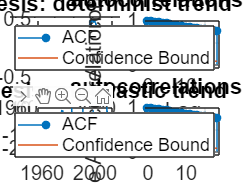


%% GRAPH OF THE DATA

figure(2)
subplot(2,2,1)
plot(t,c_sp)
title('Hypothesis: determinist trend') 
set(gca,'FontSize',15)
subplot(2,2,2)
autocorr(c_sp, 'NumLags', 18)
title('autocorrelations: c_sp')
set(gca,'FontSize',15)
dt = t(1:T-1);

subplot(2,2,3)
plot(dt,d_sp)
title('Hypothesis: stochastic trend') 
set(gca,'FontSize',15)
subplot(2,2,4)
autocorr(c_sp, 'NumLags', 18)
title('autocorrelations: d_sp')
set(gca,'FontSize',15)